# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 12-Jun-2021 16:18:00

## Set up the Import Options and import the data

clc
clear all
opts = spreadsheetImportOptions("NumVariables", 25);

% Specify sheet and range
opts.Sheet = "Data";
opts.DataRange = "B2:Z2190";

% Specify column names and types
opts.VariableNames = ["Capacitance", "Power", "Energy", "ElectMG", "HeatT", "SSA", "IDIG", "Nconcentration", "Oconcentration", "Pconcentration", "Bconcentration", "Porosity", "PoreVolumecm3g", "PreparationMG", "ElectrolyteType", "Electrolyteconcentration", "NormalizedScanRate", "AbsolutePotentialWindow", "Separator", "CurrentCollector", "SaltAnionVolume", "SaltCationVolume", "SolventDipoleMoment", "SolventVolume", "BinderConc"];
opts.VariableTypes = ["double", "double", "double", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical", "categorical", "double", "double", "double", "categorical", "categorical", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, ["ElectMG", "PreparationMG", "ElectrolyteType", "Separator", "CurrentCollector"], "EmptyFieldRule", "auto");

% Import the data
DataSet = readtable("D:\Kullanıcılar\canko\OneDrive\Masaüstü\Tubitak\100 Makale\DataSet.xlsx", opts, "UseExcel", false);

## Clear temporary variables

%Remove other response variables
Inputs = removevars(DataSet,[1,2]);

%Remove outlier data
%By changing round(control) value someone can adjust amount of data
%preserved throughout the code. This is done to decrease RMSE. 
control=0;
i=0;
while round(control)~=70
control= (size(Inputs(Inputs.Energy<i,:),1)/size(Inputs,1))*100;
control;
i=i+1;
end
threshold=i;
Inputs= Inputs(Inputs.Energy<threshold,:);
Inputs= Inputs(Inputs.PoreVolumecm3g<70,:); %pore volume values lower than 70 rows eliminated

%Normalize numerical data
numeric= removevars(Inputs, [2,12,13,17,18]);

% normalized data except target variable to get rid of scale inconsistance
numeric{:, 2:end} = normalize(numeric{:, 2:end},'range',[0 1]);
categoric=Inputs(:,[2,12,13,17,18]);
Inputs=[numeric categoric];

Inputs = movevars(Inputs,'Energy','After','CurrentCollector'); %Energy output removed to the last column

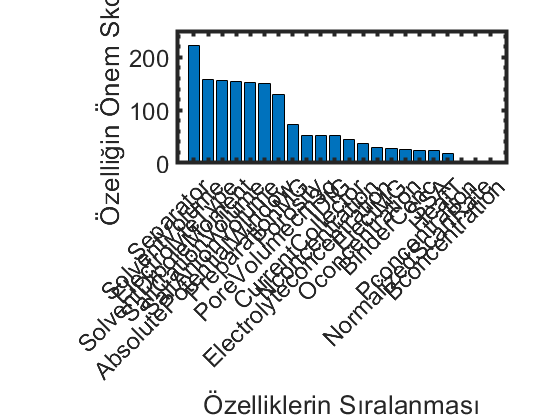

%F-Test: First feature selection method

[idx,scores] = fsrftest(Inputs,"Energy");

find(isinf(scores));

bar(scores(idx))
xlabel('Özelliklerin Sıralanması')
ylabel('Özelliğin Önem Skoru')
labels=Inputs.Properties.VariableNames(idx);
xticks(1:22) %Labellar arasındaki uzaklığı ayarlıyor
xticklabels(strrep(Inputs.Properties.VariableNames(idx),'_','\_'))
xtickangle(45)
set(gca,'FontSize',18)
set(gca,'YMinorTick','on')
set(gca,'linewidth',3)

Inputs(:,idx);

Inputs=removevars(Inputs, [idx(end),idx(end-1),idx(end-2)]);

% REMOVE FEATURES ACCORDİNG TO TRİAL&ERROR METHOD 
Inputs=removevars(Inputs, ["HeatT","Nconcentration","Oconcentration","Porosity","PoreVolumecm3g", ...
    "SaltAnionVolume","SaltCationVolume","BinderConc","ElectrolyteType", ...
    "CurrentCollector","SolventDipoleMoment","ElectMG"]);

Data=Inputs; %Store data as categorical to use suitable models
%Dummy Coding

%Dummy_ElectMG=array2table(dummyvar(Inputs.ElectMG), ...
%    'VariableNames',{'ElectMG1','ElectMG2','ElectMG3','ElectMG4','ElectMG5','ElectMG6','ElectMG7','ElectMG8','ElectMG9','ElectMG10','ElectMG11','ElectMG12','ElectMG13','ElectMG14','ElectMG15'});
Dummy_PreparationMG=array2table(dummyvar(Inputs.PreparationMG), ...
     "VariableNames",{'Dummy_PreparationMG1','Dummy_PreparationMG2','Dummy_PreparationMG3','Dummy_PreparationMG4','Dummy_PreparationMG5','Dummy_PreparationMG6','Dummy_PreparationMG7','Dummy_PreparationMG8','Dummy_PreparationMG9','Dummy_PreparationMG10','Dummy_PreparationMG11'});
%Dummy_ElectrolyteType=array2table(dummyvar(Inputs.ElectrolyteType) ...
%    ,"VariableNames",{'ElectrolyteType1','ElectrolyteType2','ElectrolyteType3',});
Dummy_Separator=array2table(dummyvar(Inputs.Separator), ...
    "VariableNames",{'Separator1','Separator2','Separator3','Separator4','Separator5','Separator6','Separator7'});
%Dummy_CurrentCollector=array2table(dummyvar(Inputs.CurrentCollector), ...
%    "VariableNames",{'CurrentCollector1','CurrentCollector2','CurrentCollector3','CurrentCollector4','CurrentCollector5','CurrentCollector6','CurrentCollector7','CurrentCollector8','CurrentCollector9','CurrentCollector10','CurrentCollector11'});
ResponseVar=array2table(Inputs.Energy); 

%'ElectMG','ElectrolyteType','CurrentCollector',
% Dummy_ElectMG Dummy_ElectrolyteType Dummy_CurrentCollector

Inputs=removevars(Inputs, {'PreparationMG', 'Separator',  'Energy'});

Inputs=[Inputs  Dummy_PreparationMG  Dummy_Separator  ResponseVar]

Inputs = 1521×24 table
      SSA       IDIG      Electrolyteconcentration    AbsolutePotentialWindow    SolventVolume    Dummy_PreparationMG1    Dummy_PreparationMG2    Dummy_PreparationMG3    Dummy_PreparationMG4    Dummy_PreparationMG5    Dummy_PreparationMG6    Dummy_PreparationMG7    Dummy_PreparationMG8    Dummy_PreparationMG9    Dummy_PreparationMG10    Dummy_PreparationMG11    Separator1    Separator2    Separator3    Separator4    Separator5    Separator6    Separator7     Var1 
    _______    _______    ________________________

Inputs.Properties.VariableNames{'Var1'} ='Energy'

Inputs = 1521×24 table
      SSA       IDIG      Electrolyteconcentration    AbsolutePotentialWindow    SolventVolume    Dummy_PreparationMG1    Dummy_PreparationMG2    Dummy_PreparationMG3    Dummy_PreparationMG4    Dummy_PreparationMG5    Dummy_PreparationMG6    Dummy_PreparationMG7    Dummy_PreparationMG8    Dummy_PreparationMG9    Dummy_PreparationMG10    Dummy_PreparationMG11    Separator1    Separator2    Separator3    Separator4    Separator5    Separator6    Separator7    Energy
    _______    _______    ________________________

%Splitting data to train,test and validation with K-Fold Cross validation
%for the dummied data
rand_num = randperm(size(Inputs,1));
%Splitting Train and Test Data 90% of data
InputsTT=table2array(Inputs(rand_num(1:round(0.9*length(rand_num))),:));

%Splitting Validation Data 10% of data
InputV = table2array(Inputs(rand_num(round(0.9*length(rand_num))+1:end),:));
InputValidX=InputV(:,1:size(InputV,2)-1);
InputValidY=InputV(:,size(InputV,2));

%Cross validation
c = cvpartition(size(InputsTT,1),'KFold',5); %80% of data train 20% of data test
idx1=training(c,1);
idx2=training(c,2);
idx3=training(c,3);
idx4=training(c,4);
idx5=training(c,5);


InputTrain1 = (InputsTT(idx1,:));
InputTrainX1 = InputTrain1(:,1:size(InputTrain1,2)-1);
InputTrainY1 = InputTrain1(:,size(InputTrain1,2));
InputTest1 = (InputsTT(~idx1,:));
InputTestX1 = InputTest1(:,1:size(InputTest1,2)-1);
InputTestY1 = InputTest1(:,size(InputTest1,2));

InputTrain2 = (InputsTT(idx2,:));
InputTrainX2 = InputTrain2(:,1:size(InputTrain2,2)-1);
InputTrainY2 = InputTrain2(:,size(InputTrain2,2));
InputTest2 = (InputsTT(~idx2,:));
InputTestX2 = InputTest2(:,1:size(InputTest2,2)-1);
InputTestY2 = InputTest2(:,size(InputTest2,2));

InputTrain3 = (InputsTT(idx3,:));
InputTrainX3 = InputTrain3(:,1:size(InputTrain3,2)-1);
InputTrainY3 = InputTrain3(:,size(InputTrain3,2));
InputTest3 = (InputsTT(~idx3,:));
InputTestX3 = InputTest3(:,1:size(InputTest3,2)-1);
InputTestY3 = InputTest3(:,size(InputTest3,2));

InputTrain4 = (InputsTT(idx4,:));
InputTrainX4 = InputTrain4(:,1:size(InputTrain4,2)-1);
InputTrainY4 = InputTrain4(:,size(InputTrain4,2));
InputTest4 = (InputsTT(~idx4,:));
InputTestX4 = InputTest4(:,1:size(InputTest4,2)-1);
InputTestY4 = InputTest4(:,size(InputTest4,2));

InputTrain5 = (InputsTT(idx5,:));
InputTrainX5 = InputTrain5(:,1:size(InputTrain5,2)-1);
InputTrainY5 = InputTrain5(:,size(InputTrain5,2));
InputTest5 = (InputsTT(~idx5,:));
InputTestX5 = InputTest5(:,1:size(InputTest5,2)-1);
InputTestY5 = InputTest5(:,size(InputTest5,2));

InputTrainX= {InputTrainX1 InputTrainX2 InputTrainX3 InputTrainX4 InputTrainX5};
InputTrainY= {InputTrainY1 InputTrainY2 InputTrainY3 InputTrainY4 InputTrainY5};

InputTestX= {InputTestX1 InputTestX2 InputTestX3 InputTestX4 InputTestX5};
InputTestY= {InputTestY1 InputTestY2 InputTestY3 InputTestY4 InputTestY5};

%Splitting data to train,test and validation with K-Fold Cross validation
%for the catorical data included

c = cvpartition(size(Data,1),'KFold',5); %80% of data train 20% of data test
idx1=training(c,1);
idx2=training(c,2);
idx3=training(c,3);
idx4=training(c,4);
idx5=training(c,5);


dataTrain1 = (Data(idx1,:));
dataTrainX1 = dataTrain1(:,1:size(dataTrain1,2)-1);
dataTrainY1 = dataTrain1(:,size(dataTrain1,2));
dataTest1 = (Data(~idx1,:));
dataTestX1 = dataTest1(:,1:size(dataTest1,2)-1);
dataTestY1 = dataTest1(:,size(dataTest1,2));

dataTrain2 = (Data(idx2,:));
dataTrainX2 = dataTrain2(:,1:size(dataTrain2,2)-1);
dataTrainY2 = dataTrain2(:,size(dataTrain2,2));
dataTest2 = (Data(~idx2,:));
dataTestX2 = dataTest2(:,1:size(dataTest2,2)-1);
dataTestY2 = dataTest2(:,size(dataTest2,2));

dataTrain3 = (Data(idx3,:));
dataTrainX3 = dataTrain3(:,1:size(dataTrain3,2)-1);
dataTrainY3 = dataTrain3(:,size(dataTrain3,2));
dataTest3 = (Data(~idx3,:));
dataTestX3 = dataTest3(:,1:size(dataTest3,2)-1);
dataTestY3 = dataTest3(:,size(dataTest3,2));

dataTrain4 = (Data(idx4,:));
dataTrainX4 = dataTrain4(:,1:size(dataTrain4,2)-1);
dataTrainY4 = dataTrain4(:,size(dataTrain4,2));
dataTest4 = (Data(~idx4,:));
dataTestX4 = dataTest4(:,1:size(dataTest4,2)-1);
dataTestY4 = dataTest4(:,size(dataTest4,2));

dataTrain5 = (Data(idx5,:));
dataTrainX5 = dataTrain5(:,1:size(dataTrain5,2)-1);
dataTrainY5 = dataTrain5(:,size(dataTrain5,2));
dataTest5 = (Data(~idx5,:));
dataTestX5 = dataTest5(:,1:size(dataTest5,2)-1);
dataTestY5 = dataTest5(:,size(dataTest5,2));

%TUNING LASSO ALPHA
lasso_validRMSE_tune= [];

for i=1:5
    Alpha_trial=[0.1 0.25 0.5 0.75 1];
    [B lassoReg_tune]=lasso(cell2mat(InputTrainX(1)),cell2mat(InputTrainY(1)),"Alpha",Alpha_trial(:,i),"CV",5);
    idxLambda1SE_tune= lassoReg_tune.Index1SE;
    coef_tune = B(:,idxLambda1SE_tune);
    coef0_tune = lassoReg_tune.Intercept(idxLambda1SE_tune);
    
    lasso_validPred_tune = InputValidX*coef_tune + coef0_tune;
    lasso_validRMSE_tune(:,i) = sqrt(mean((InputValidY-lasso_validPred_tune).^2));
end
[RMSE_min index_alpha]=min(lasso_validRMSE_tune);
alpha_tuned=Alpha_trial(index_alpha)

alpha_tuned = 0.1000

%TUNİNG RİDGE k
ridge_validRMSE_tune= [];
for i=1:25
k_trial = [0.1:0.2:5]; %Ridge parametrelerini araştır.
ridge_reg_tune =ridge(cell2mat(InputTrainY(1)),cell2mat(InputTrainX(1)),k_trial(i),0);
ridge_validPred = ridge_reg_tune(1) + InputValidX*ridge_reg_tune(2:end);
ridge_validRMSE(:,i) = sqrt(mean((InputValidY-ridge_validPred).^2));
end
[RMSE_min index_k]=min(ridge_validRMSE);
k_tuned=k_trial(index_k)

k_tuned = 4.9000

%Fit&Predict Linear Regression
for i=1:5
linearReg = fitlm(cell2mat(InputTrainX(i)),cell2mat(InputTrainY(i)));
linear_trainPred{i} = predict(linearReg,cell2mat(InputTrainX(i)));
linear_testPred{i} = predict(linearReg,cell2mat(InputTestX(i)));
linear_trainRMSE{i} = sqrt(mean((cell2mat(InputTrainY(i))-cell2mat(linear_trainPred(i))).^2));
linear_testRMSE{i} = sqrt(mean((cell2mat(InputTestY(i))-cell2mat(linear_testPred(i))).^2));
linear_testRMSE0{i} = std(cell2mat(InputTestY(i))-mean(cell2mat(InputTestY(i))).^2);
end

avg_linear_trainRMSE=mean(cell2mat(linear_trainRMSE))

avg_linear_trainRMSE = 5.2557

avg_linear_testRMSE=mean(cell2mat(linear_testRMSE))

avg_linear_testRMSE = 5.3519

avg_linear_testRMSE0=mean(cell2mat(linear_testRMSE0));
r_sq=1-(avg_linear_testRMSE/avg_linear_testRMSE0)

r_sq = 0.2767

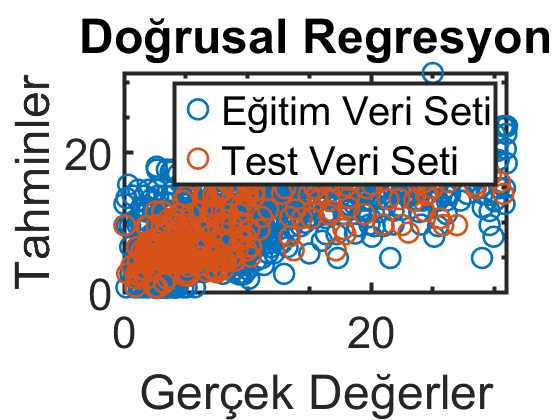

% Plot for Linear Regression
for i=1:5
plot(cell2mat(InputTrainY(i)),cell2mat(linear_trainPred(i)),'o','LineWidth',2,'MarkerSize',15)
hold on 
plot(cell2mat(InputTestY(i)),cell2mat(linear_testPred(i)),'o','LineWidth',2,'MarkerSize',15)
hold off
end
legend('Eğitim Veri Seti','Test Veri Seti'); 
xlabel('Gerçek Değerler');
ylabel ('Tahminler'); 
title('Doğrusal Regresyon')
set(gca,'FontSize',33)
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'TickLength',[0.02,0.05])
set(gca,'linewidth',3)

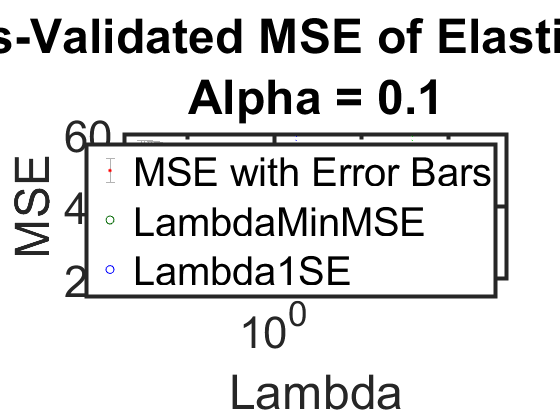

%Lasso
%To find lambda min
[P, lassoRegres]=lasso(cell2mat(InputTrainX(1)),cell2mat(InputTrainY(1)),'Alpha',alpha_tuned,'CV',5);
lassoPlot(P,lassoRegres,'PlotType',"CV")
legend('show')
set(gca,'FontSize',33)
set(gca,'TickLength',[0.02,0.05])
set(gca,'linewidth',3)

%Lambda min used and model is trained
minLambda=lassoRegres.LambdaMinMSE; %Değiştir DYNAMİC yap
[A,lassoReg]=lasso(cell2mat(InputTrainX(1)),cell2mat(InputTrainY(1)),'Lambda',minLambda,'Alpha',alpha_tuned,'CV',5);
idxLambda1SE = lassoReg.Index1SE;
coef = A(:,idxLambda1SE);
coef0 = lassoReg.Intercept(idxLambda1SE);

%Predictions and test errors for lasso regresion
for i=1:5
lasso_trainPred{i} = cell2mat(InputTrainX(i))*coef + coef0;
lasso_testPred{i} = cell2mat(InputTestX(i))*coef + coef0;
lasso_trainRMSE{i} = sqrt(mean((cell2mat(InputTrainY(i))-cell2mat(lasso_trainPred(i))).^2));
lasso_testRMSE{i} = sqrt(mean((cell2mat(InputTestY(i))-cell2mat(lasso_testPred(i))).^2));
lasso_testRMSE0{i} = std(cell2mat(InputTestY(i))-mean(cell2mat(InputTestY(i))).^2);
end
avg_lasso_trainRMSE=mean(cell2mat(lasso_trainRMSE))

avg_lasso_trainRMSE = 5.2787

avg_lasso_testRMSE=mean(cell2mat(lasso_testRMSE))

avg_lasso_testRMSE = 5.2762

avg_lasso_testRMSE0=mean(cell2mat(lasso_testRMSE0));
r_sq=1-(avg_lasso_testRMSE/avg_lasso_testRMSE0)

r_sq = 0.2869

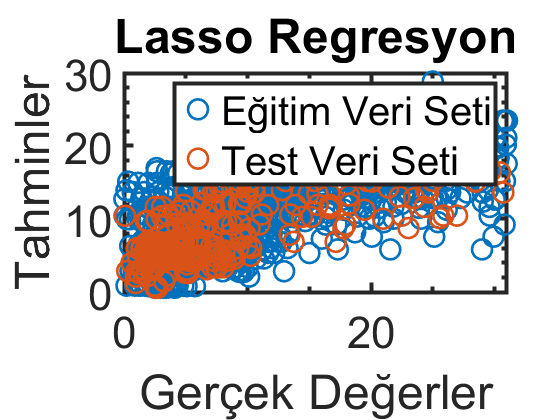

% Plot for Lasso Regression
for i=1:5
plot(cell2mat(InputTrainY(i)),cell2mat(lasso_trainPred(i)),'o','LineWidth',2,'MarkerSize',15)
hold on 
plot(cell2mat(InputTestY(i)),cell2mat(lasso_testPred(i)),'o','LineWidth',2,'MarkerSize',15)
hold off
end
legend('Eğitim Veri Seti','Test Veri Seti'); 
xlabel('Gerçek Değerler');
ylabel ('Tahminler'); title('Lasso Regresyon')
set(gca,'FontSize',33)
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'TickLength',[0.02,0.05])
set(gca,'linewidth',3)

%Fit&Predict Regression Tree
RegressionTree = fitrtree(dataTrainX1,dataTrainY1);
regtree_trainPred1 = predict(RegressionTree,dataTrainX1);
regtree_testPred1 = predict(RegressionTree,dataTestX1);
regtree_trainRMSE1 = sqrt(mean((table2array(dataTrainY1)-regtree_trainPred1).^2));
regtree_testRMSE1 = sqrt(mean((table2array(dataTestY1)-regtree_testPred1).^2));
regtree_testRMSE01 = std((table2array(dataTestY1)-mean(table2array(dataTestY1))).^2);

RegressionTree = fitrtree(dataTrainX2,dataTrainY2);
regtree_trainPred2 = predict(RegressionTree,dataTrainX2);
regtree_testPred2 = predict(RegressionTree,dataTestX2);
regtree_trainRMSE2 = sqrt(mean((table2array(dataTrainY2)-regtree_trainPred2).^2));
regtree_testRMSE2 = sqrt(mean((table2array(dataTestY2)-regtree_testPred2).^2));
regtree_testRMSE02 = std((table2array(dataTestY2)-mean(table2array(dataTestY2))).^2);

RegressionTree = fitrtree(dataTrainX3,dataTrainY3);
regtree_trainPred3 = predict(RegressionTree,dataTrainX3);
regtree_testPred3 = predict(RegressionTree,dataTestX3);
regtree_trainRMSE3 = sqrt(mean((table2array(dataTrainY3)-regtree_trainPred3).^2));
regtree_testRMSE3 = sqrt(mean((table2array(dataTestY3)-regtree_testPred3).^2));
regtree_testRMSE03 = std((table2array(dataTestY3)-mean(table2array(dataTestY3))).^2);

RegressionTree = fitrtree(dataTrainX4,dataTrainY4);
regtree_trainPred4 = predict(RegressionTree,dataTrainX4);
regtree_testPred4 = predict(RegressionTree,dataTestX4);
regtree_trainRMSE4 = sqrt(mean((table2array(dataTrainY4)-regtree_trainPred4).^2));
regtree_testRMSE4 = sqrt(mean((table2array(dataTestY4)-regtree_testPred4).^2));
regtree_testRMSE04 = std((table2array(dataTestY4)-mean(table2array(dataTestY4))).^2);

RegressionTree = fitrtree(dataTrainX5,dataTrainY5);
regtree_trainPred5 = predict(RegressionTree,dataTrainX5);
regtree_testPred5 = predict(RegressionTree,dataTestX5);
regtree_trainRMSE5 = sqrt(mean((table2array(dataTrainY5)-regtree_trainPred5).^2));
regtree_testRMSE5 = sqrt(mean((table2array(dataTestY5)-regtree_testPred5).^2));
regtree_testRMSE05 = std((table2array(dataTestY5)-mean(table2array(dataTestY5))).^2);

avg_regtree_trainRMSE=(regtree_trainRMSE1+regtree_trainRMSE2+regtree_trainRMSE3+regtree_trainRMSE4+regtree_trainRMSE5 )/5

avg_regtree_trainRMSE = 2.9317

avg_regtree_testRMSE=(regtree_testRMSE1+regtree_testRMSE2+regtree_testRMSE3+regtree_testRMSE4+regtree_testRMSE5)/5

avg_regtree_testRMSE = 3.8774

avg_regtree_testRMSE0=(regtree_testRMSE01+regtree_testRMSE02+regtree_testRMSE03+regtree_testRMSE04+regtree_testRMSE05)/5;

r_sq=1-(avg_regtree_testRMSE/avg_regtree_testRMSE0)

r_sq = 0.9544

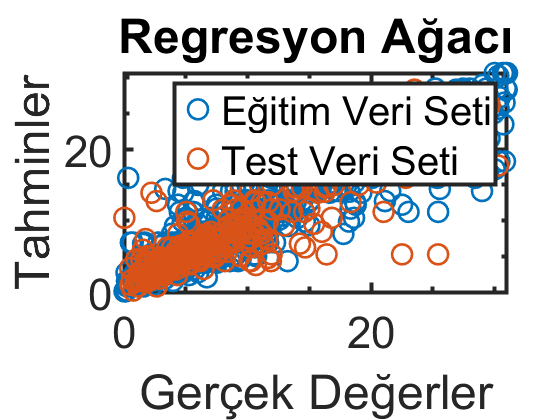

% Plot for Regression Tree 
plot(table2array(dataTrainY1),regtree_trainPred1,'o','LineWidth',2,'MarkerSize',15)
hold on 
plot(table2array(dataTestY1),regtree_testPred1,'o','LineWidth',2,'MarkerSize',15)
hold off
legend('Eğitim Veri Seti','Test Veri Seti'); 
xlabel('Gerçek Değerler');
ylabel ('Tahminler'); title('Regresyon Ağacı')
set(gca,'FontSize',33)
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'TickLength',[0.02,0.05])
set(gca,'linewidth',3)

%   Ridge model training&predictions
k = k_tuned; 
for i=1:5
ridge_reg =ridge(cell2mat(InputTrainY(i)),cell2mat(InputTrainX(i)),k,0);
ridge_trainPred{i} = ridge_reg(1) + cell2mat(InputTrainX(i))*ridge_reg(2:end);
ridge_testPred{i} = ridge_reg(1) + cell2mat(InputTestX(i))*ridge_reg(2:end);
ridge_trainRMSE{i} = sqrt(mean((cell2mat(InputTrainY(i))-cell2mat(ridge_trainPred(i))).^2));
ridge_testRMSE{i} = sqrt(mean((cell2mat(InputTestY(i))-cell2mat(ridge_testPred(i))).^2));
ridge_testRMSE0{i} = std(cell2mat(InputTestY(i))-mean(cell2mat(InputTestY(i))).^2);
end
avg_ridge_trainRMSE=mean(cell2mat(ridge_trainRMSE))

avg_ridge_trainRMSE = 5.2558

avg_ridge_testRMSE=mean(cell2mat(ridge_testRMSE))

avg_ridge_testRMSE = 5.3515

avg_ridge_testRMSE0=mean(cell2mat(ridge_testRMSE0));

r_sq=1-(avg_ridge_testRMSE/avg_ridge_testRMSE0)

r_sq = 0.2767

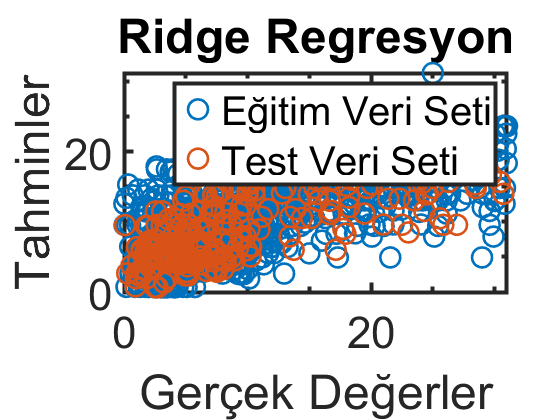

%plot ridge regression
for i=1:5
plot(cell2mat(InputTrainY(i)),cell2mat(ridge_trainPred(i)),'o','LineWidth',2,'MarkerSize',15)
hold on 
plot(cell2mat(InputTestY(i)),cell2mat(ridge_testPred(i)),'o','LineWidth',2,'MarkerSize',15)
hold off
end
legend('Eğitim Veri Seti','Test Veri Seti'); 
xlabel('Gerçek Değerler');
ylabel ('Tahminler'); title('Ridge Regresyon')
set(gca,'FontSize',33)
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'TickLength',[0.02,0.05])
set(gca,'linewidth',3)

%Neural Network Modelling
hiddenLayerSize = 25

hiddenLayerSize = 25

trainFcn = 'trainlm'

trainFcn = 'trainlm'

net = fitnet(hiddenLayerSize,trainFcn)

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 25
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input

net.divideParam.trainRatio = 72/100;
net.divideParam.valRatio = 10/100;
net.divideParam.testRatio = 18/100;

rng('default')
[NeuralNet, err] = train(net,(table2array(Inputs(:,1:end-1)))', (Inputs.Energy)')

NeuralNet =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 576
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      

err = struct with fields:
        trainFcn: 'trainlm'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1×1095 double]
          valInd: [1×152 double]
         testInd: [1×274 double]
            stop: 'Validation stop.'
      num_epochs: 18
       trainMask: {[1×1521 double]}
         valMask: {[1×1521 double]}
        testMask: {[1×1521 double]}
      best_epoch: 12
            goal: 0
          states: {'epoch'  'time'  'perf'  'vperf'  'tperf'  'mu'  'gradient'  'val_fail'}
           epoch: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18]
            time: [0.8120 0.9070 0.9540 0.9990 1.0330 1.0750 1.0970 1.1150 1.1370 1.1560 1.1750 1.1920 1.2140 1.2340 1.2540 1.2750 1.2930 1.3180 1.3360]
            perf: [427.6087 71.7140 51.6922 24.4489 18.7561 16.9825 16.1187 15.7309 15.4364 15.2200 15.0317 14.8649 14.